function [upper_half_circles, lower_half_circles, ...
          upper_random_point, lower_random_point, external_random_point, r_values] = define_concentric_circles()
    num_points = 500;
    r_values = 0.05:0.05:1; % Radius values from 0.05 to 1, generating concentric circles at intervals of 0.05
    upper_half_circles = cell(1, length(r_values));
    lower_half_circles = cell(1, length(r_values));
    theta_upper = linspace(0, pi, num_points);
    theta_lower = linspace(pi, 2*pi, num_points);

    % Use smoother gradient colors
    colors_upper = [linspace(1, 1, length(r_values))', linspace(1, 0.5, length(r_values))', linspace(0.2, 0, length(r_values))']; % Light yellow to red
    colors_lower = [linspace(0.2, 0, length(r_values))', linspace(1, 0.5, length(r_values))', linspace(0.2, 1, length(r_values))']; % Light green to blue

    for k = 1:length(r_values)
        r = r_values(k);
        upper_half_circles{k} = struct('points', r * exp(1i * theta_upper), 'color', colors_upper(k, :)); % Upper half circle from light yellow to red
        lower_half_circles{k} = struct('points', r * exp(1i * theta_lower), 'color', colors_lower(k, :)); % Lower half circle from light green to blue
    end

    % Special handling for the outermost circle
    upper_half_circles{end}.color = [1, 0, 0]; % Red
    lower_half_circles{end}.color = [0, 0, 1]; % Blue

    % Example data (these can be modified as needed)
    upper_random_point = 0.5 * exp(1i * (pi * rand)); % Random point in the upper half of the unit circle
    lower_random_point = 0.5 * exp(1i * (pi * rand + pi)); % Random point in the lower half of the unit circle
    external_random_point = 1.5 * exp(1i * (2 * pi * rand)); % Random point outside the unit circle
end




function plot_all_circles(upper_half_circles, lower_half_circles, upper_random_point, lower_random_point, external_random_point, title_text, r_values)
    figure;
    hold on;
    % Iterate through all concentric circles
    for k = 1:length(upper_half_circles)
        if isstruct(upper_half_circles{k})
            plot(real(upper_half_circles{k}.points), imag(upper_half_circles{k}.points), 'Color', upper_half_circles{k}.color, 'LineWidth', 1.5, 'DisplayName', ['r = ' num2str(r_values(k))]);
            plot(real(lower_half_circles{k}.points), imag(lower_half_circles{k}.points), 'Color', lower_half_circles{k}.color, 'LineWidth', 1.5, 'DisplayName', ['r = ' num2str(r_values(k))]);
        end
    end

%     % Add a red arrow from the fifth to the sixth point on the upper half of the outermost circle
%     if isstruct(upper_half_circles{end})
%         points_upper = upper_half_circles{end}.points;
%         quiver(real(points_upper(5)), imag(points_upper(5)), real(points_upper(6)) - real(points_upper(5)), imag(points_upper(6)) - imag(points_upper(5)), ...
%                'r', 'MaxHeadSize', 10, 'LineWidth', 3, 'AutoScaleFactor', 10, 'DisplayName', 'Arrow Upper');
%     end
% 
%     % Add a blue arrow from the fifth to the sixth point on the lower half of the outermost circle
%     if isstruct(lower_half_circles{end})
%         points_lower = lower_half_circles{end}.points;
%         quiver(real(points_lower(5)), imag(points_lower(5)), real(points_lower(6)) - real(points_lower(5)), imag(points_lower(6)) - imag(points_lower(5)), ...
%                'b', 'MaxHeadSize', 10, 'LineWidth', 3, 'AutoScaleFactor', 10, 'DisplayName', 'Arrow Lower');
%     end

    plot(real(upper_random_point), imag(upper_random_point), 'ko', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Upper Random Point');
    plot(real(lower_random_point), imag(lower_random_point), 'bo', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Lower Random Point');
    plot(real(external_random_point), imag(external_random_point), 'go', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'External Random Point');
    title(title_text);
    xlabel('Real part');
    ylabel('Imaginary part');
    grid on;
    axis equal;
    xlim([-2.5, 2.5]);
    ylim([-2.5, 2.5]);
    legend('show', 'Location', 'eastoutside'); % Display legend outside the plot
    hold off;
end


function [mapped_upper_half_circles, mapped_lower_half_circles, mapped_upper_random_point, mapped_lower_random_point, mapped_external_random_point] = apply_conformal_mapping(map_func, upper_half_circles, lower_half_circles, upper_random_point, lower_random_point, external_random_point)
    % Apply the mapping function to the upper half circles
    mapped_upper_half_circles = cellfun(@(c) struct('points', map_func(c.points), 'color', c.color), upper_half_circles, 'UniformOutput', false);
    
    % Apply the mapping function to the lower half circles
    mapped_lower_half_circles = cellfun(@(c) struct('points', map_func(c.points), 'color', c.color), lower_half_circles, 'UniformOutput', false);
    
    % Apply the mapping function to the random points
    mapped_upper_random_point = map_func(upper_random_point);
    mapped_lower_random_point = map_func(lower_random_point);
    mapped_external_random_point = map_func(external_random_point);
end

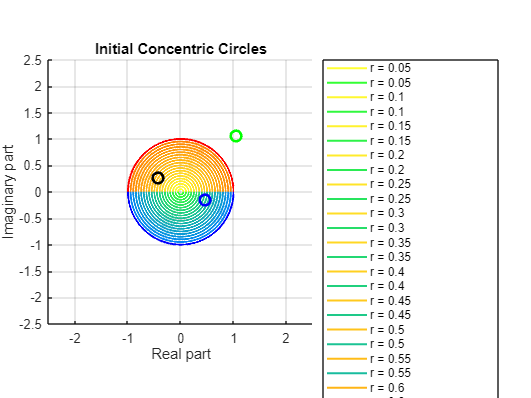

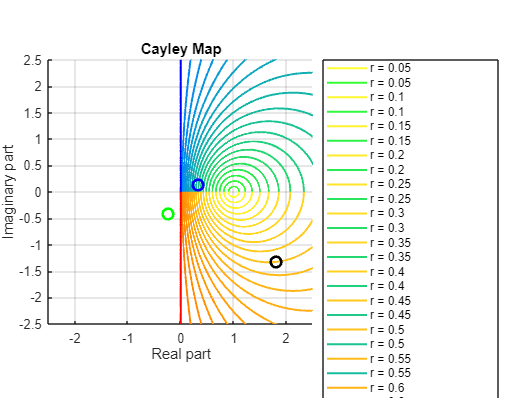

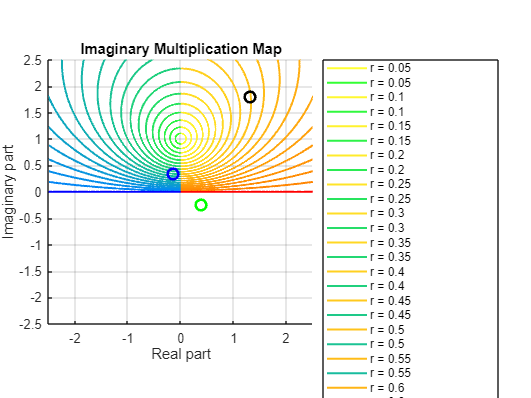

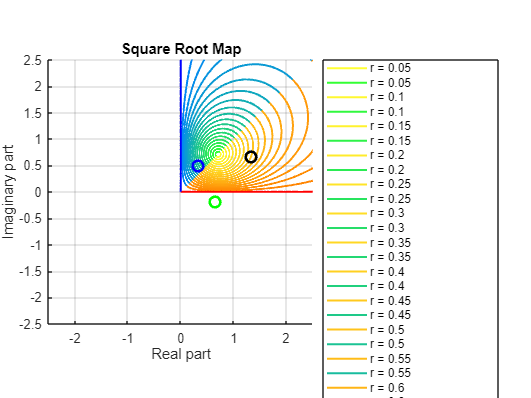

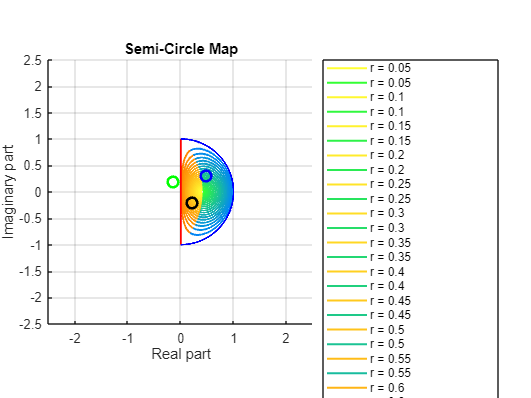

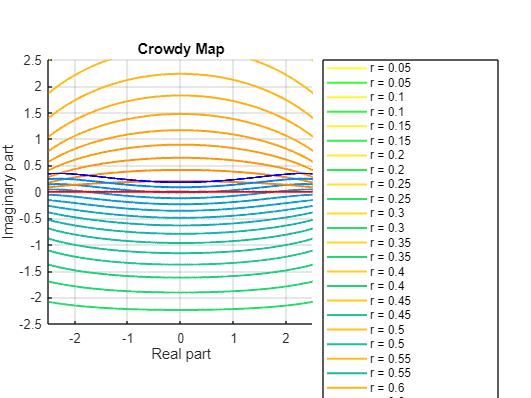

% Main function to perform conformal mappings and plot results
function main()
    % Define concentric circles
    [upper_half_circles, lower_half_circles, upper_random_point, lower_random_point, external_random_point, r_values] = define_concentric_circles();

    % Plot initial concentric circles
    plot_all_circles(upper_half_circles, lower_half_circles, upper_random_point, lower_random_point, external_random_point, 'Initial Concentric Circles', r_values);

    % Modify r=1 line for better visualization before first mapping
    r_adjustment = 1 - 1e-15;
    upper_half_circles{end}.points = upper_half_circles{end}.points * r_adjustment;
    lower_half_circles{end}.points = lower_half_circles{end}.points * r_adjustment;

    % First Mapping (Cayley Map)
    cayley_map = @(zeta) (1 - zeta) ./ (1 + zeta);
    [mapped_upper_half_circles, mapped_lower_half_circles, mapped_upper_random_point, mapped_lower_random_point, mapped_external_random_point] = apply_conformal_mapping(cayley_map, upper_half_circles, lower_half_circles, upper_random_point, lower_random_point, external_random_point);

    % Plot the data after the first mapping
    plot_all_circles(mapped_upper_half_circles, mapped_lower_half_circles, mapped_upper_random_point, mapped_lower_random_point, mapped_external_random_point, 'Cayley Map', r_values);

    % Second Mapping
    second_map = @(zeta_1) (i * zeta_1);
    [mapped_upper_half_circles_second, mapped_lower_half_circles_second, mapped_upper_random_point_second, mapped_lower_random_point_second, mapped_external_random_point_second] = apply_conformal_mapping(second_map, mapped_upper_half_circles, mapped_lower_half_circles, mapped_upper_random_point, mapped_lower_random_point, mapped_external_random_point);

    % Plot the data after the second mapping
    plot_all_circles(mapped_upper_half_circles_second, mapped_lower_half_circles_second, mapped_upper_random_point_second, mapped_lower_random_point_second, mapped_external_random_point_second, 'Imaginary Multiplication Map', r_values);

    % Third Mapping
    sqrt_map = @(zeta_2) sqrt(zeta_2);
    [mapped_upper_half_circles_third, mapped_lower_half_circles_third, mapped_upper_random_point_third, mapped_lower_random_point_third, mapped_external_random_point_third] = apply_conformal_mapping(sqrt_map, mapped_upper_half_circles_second, mapped_lower_half_circles_second, mapped_upper_random_point_second, mapped_lower_random_point_second, mapped_external_random_point_second);

    % Plot the data after the third mapping
    plot_all_circles(mapped_upper_half_circles_third, mapped_lower_half_circles_third, mapped_upper_random_point_third, mapped_lower_random_point_third, mapped_external_random_point_third, 'Square Root Map', r_values);

    % Fourth Mapping
    fourth_map = @(zeta_3) i * (1 - zeta_3) ./ (1 + zeta_3);
    [mapped_upper_half_circles_fourth, mapped_lower_half_circles_fourth, mapped_upper_random_point_fourth, mapped_lower_random_point_fourth, mapped_external_random_point_fourth] = apply_conformal_mapping(fourth_map, mapped_upper_half_circles_third, mapped_lower_half_circles_third, mapped_upper_random_point_third, mapped_lower_random_point_third, mapped_external_random_point_third);

    % Modify the r=1 upper and lower half circles in the fourth mapping
    num_points = 5000;
    mapped_upper_half_circles_fourth{end}.points = linspace(1i, -1i, num_points); % y-axis from y = 1 to y = -1
    mapped_lower_half_circles_fourth{end}.points = exp(1i * linspace(-pi/2, pi/2, num_points)); % r = 1, theta from -pi/2 to pi/2

    % Plot the modified data after the fourth mapping
    plot_all_circles(mapped_upper_half_circles_fourth, mapped_lower_half_circles_fourth, mapped_upper_random_point_fourth, mapped_lower_random_point_fourth, mapped_external_random_point_fourth, 'Semi-Circle Map', r_values);

    % Fifth Mapping (Crowdy Map)
    a = 3.15;
    A = (a^4 - 1) / sqrt(a^8 - 66 * a^4 - 63);
    crowdy_map = @(z) i * A * ((9*z - a^2*z.^3) ./ (1 - a^2*z.^2));
    [mapped_upper_half_circles_fifth, mapped_lower_half_circles_fifth, mapped_upper_random_point_fifth, mapped_lower_random_point_fifth, mapped_external_random_point_fifth] = apply_conformal_mapping(crowdy_map, mapped_upper_half_circles_fourth, mapped_lower_half_circles_fourth, mapped_upper_random_point_fourth, mapped_lower_random_point_fourth, mapped_external_random_point_fourth);

    % Plot the data after the fifth mapping
    plot_all_circles(mapped_upper_half_circles_fifth, mapped_lower_half_circles_fifth, mapped_upper_random_point_fifth, mapped_lower_random_point_fifth, mapped_external_random_point_fifth, 'Crowdy Map', r_values);
end

% Execute the main function
main();